The eigenvalues of advection--diffusion are near-imaginary for $\epsilon\approx 0$ and more negative-real for increasing values of $\epsilon$.

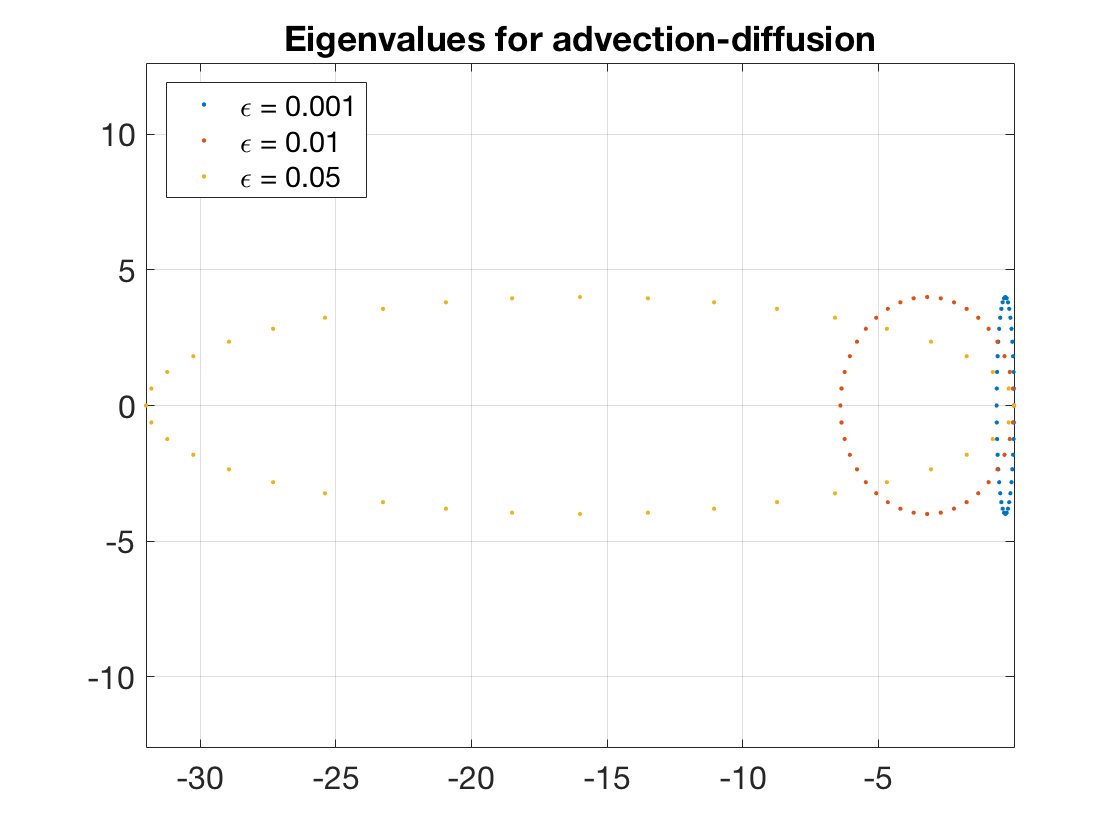

[x,Dx,Dxx] = diffper(40,[0,1]);
tau = 0.1;
for ep = [0.001 0.01 0.05]
  lambda = eig(-Dx + ep*Dxx);
  plot(real(tau*lambda),imag(tau*lambda),'.'), hold on
end
axis equal,  grid on    % ignore this line
legend('\epsilon = 0.001','\epsilon = 0.01','\epsilon = 0.05','location','northwest')    % ignore this line
title('Eigenvalues for advection-diffusion')    % ignore this line